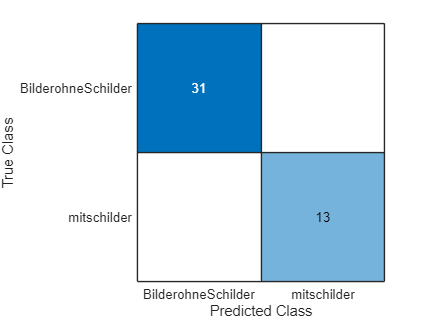

% Pfad zum Bildordner
imageFolder = 'C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\Trainingsdaten\AusgeschnittenFürTraining\TestbilderAusOpenNachBildaufnahmen3NichtZuTrain';
imdsSchilder = imageDatastore(imageFolder, "IncludeSubfolders", true, "LabelSource", "foldernames");
augTrain  = augmentedImageDatastore([48 48 3], imdsSchilder, ...
    'ColorPreprocessing', 'none', ...
    'OutputSizeMode', 'resize');

% Beispiel: Angenommen dein Netz heißt 'net'
load('meinNetz.mat'); % lädt das trainierte Netz
net = net; % falls nötig

% Bildgröße anpassen (abhängig vom Netz)
% inputSize = net.Layers(1).InputSize(1:2);

% Klassenlabels (falls vorhanden)
classNames = {'KeinSchild', 'Schild'}; % Beispiel

%Schätzung Trainingsdatensatz
tbl = readall(augTrain);           % Liefert eine Tabelle mit Bildern
imgs = tbl{:,1};                 % Hole die Bilder aus der ersten Spalte als Cell-Array
TTrain = imdsSchilder.Labels;
classNames = categories(TTrain);

XTrain = cat(4,imgs{:});
XTrain = single(XTrain);

outputs  = minibatchpredict(net,XTrain);
YTrain = onehotdecode(squeeze(outputs)',classNames,2);
confusionchart(TTrain,YTrain)

confMat = confusionmat(imdsSchilder.Labels, YTrain);
accuracy = sum(diag(confMat)) / sum(confMat(:));
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 100.00%


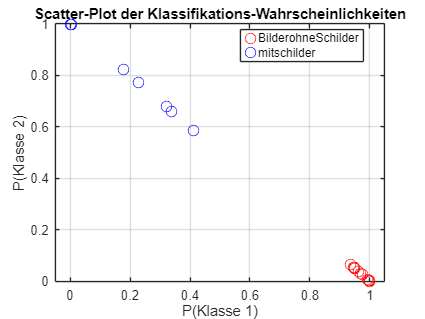


prob = squeeze(outputs); 

% 4) Scatterplot erstellen (mit Farbcode nach true Label)
figure;
gscatter(...
    prob(1,:), ...                    % X-Werte: P(Klasse 1)
    prob(2,:), ...                    % Y-Werte: P(Klasse 2)
    TTrain, ...                       % Gruppierung nach echtem Label
    'rb', ...                         % Farben: rot/blau
    'o', ...                          % Marker: Kreis
    8);                               % Markergröße

xlabel('P(Klasse 1)');
ylabel('P(Klasse 2)');
title('Scatter-Plot der Klassifikations-Wahrscheinlichkeiten');
legend(categories(TTrain), 'Location', 'best');
grid on;

%axis square;


%Falsch erkantte Bilder anzeigen
trueLabelsTrain = imdsSchilder.Labels;

wrongIdxtrain = find(YTrain ~= trueLabelsTrain);



for i = 1:length(wrongIdxtrain)
    img = readimage(imdsSchilder, wrongIdxtrain(i));
    figure;
    imshow(img);
    title(sprintf("Falsch erkannt: Vorhersage = %s, Richtig = %s", ...
        string(YTrain(wrongIdxtrain(i))), string(trueLabelsTrain(wrongIdxtrain(i)))));
end